## Padding a imatge

### Funció:

%function [J] = marc(I,N,ndg)
%s = size(I)
%J = zeros(s(1) + N*2, s(2) + N*2) + ndg
%J(N:s(1)+N-1, N:s(2)+N-1) = I;
%end
%

## Pasar a escala de grisos

I = imread('lena_color_512.tif')

I = 512×512×3 uint8 array
I(:,:,1) =

   226   226   223   223   226   226   228   227   227   225   228   225   223   226   223   221   221   221   222   222   223   223   224   221   218   221   223   225   221   221   220   223   225   223   226   223   225   227   229   231   231   232   230   233   234   237   233   231   237   238   234   235   234   232   233   230   227   221   219   213   203   202   187   174   169   166   158   153   155   157   166   161   166   165   169   170   174   174   175   180   177   178   177   177   175   175   173   179   177   178   177   178   182   178   178   179   176   179   178   174   173   174   179   180   177   182   182   185   187   190   194   194   190   199   195   193   195   196   192   201   203   202   206   197   201   205   202   206   205   207   209   203   204   205   202   204   200   206   204   206   207   204   203   206   205   207   203   201   202   203   204   202   205   201   204   202   205   207   206   206  

R = double(I(:, :, 1))

R =    226   226   223   223   226   226   228   227   227   225   228   225   223   226   223   221   221   221   222   222   223   223   224   221   218   221   223   225   221   221   220   223   225   223   226   223   225   227   229   231   231   232   230   233   234   237   233   231   237   238
   226   226   223   223   226   226   228   227   227   225   228   225   223   226   223   221   221   221   222   222   223   223   224   221   218   221   223   225   221   221   220   223   225   223   226   223   225   227   229   231   231   232   230   233   234   237   233   231   237   238
   226   226   223   223   226   226   228   227   227   225   228   225   223   226   223   221   221   221   222   222   223   223   224   221   218   221   223   225   221   221   220   223   225   223   226   223   225   227   229   231   231   232   230   233   234   237   233   231   237   238
   226   226   223   223   226   226   228   227   227   225   228   225   223   226   223   

G = double(I(:, :, 2))

G =    137   137   137   136   138   129   138   134   140   136   135   134   130   139   135   129   134   131   138   139   127   132   129   134   131   133   130   125   130   129   127   131   127   134   128   135   133   144   135   142   143   142   143   150   148   154   153   149   149   149
   137   137   137   136   138   129   138   134   140   136   135   134   130   139   135   129   134   131   138   139   127   132   129   134   131   133   130   125   130   129   127   131   127   134   128   135   133   144   135   142   143   142   143   150   148   154   153   149   149   149
   137   137   137   136   138   129   138   134   140   136   135   134   130   139   135   129   134   131   138   139   127   132   129   134   131   133   130   125   130   129   127   131   127   134   128   135   133   144   135   142   143   142   143   150   148   154   153   149   149   149
   137   137   137   136   138   129   138   134   140   136   135   134   130   139   135   

B = double(I(:, :, 3))

B =    125   125   133   128   120   116   123   124   127   119   126   121   108   119   120   114   108   113   121   114   109   105   102   109   110   113   108    98   121   111   121   109   103   109   106   122   112   124   104   123   116   112   117   121   121   123   121   121   119   116
   125   125   133   128   120   116   123   124   127   119   126   121   108   119   120   114   108   113   121   114   109   105   102   109   110   113   108    98   121   111   121   109   103   109   106   122   112   124   104   123   116   112   117   121   121   123   121   121   119   116
   125   125   133   128   120   116   123   124   127   119   126   121   108   119   120   114   108   113   121   114   109   105   102   109   110   113   108    98   121   111   121   109   103   109   106   122   112   124   104   123   116   112   117   121   121   123   121   121   119   116
   125   125   133   128   120   116   123   124   127   119   126   121   108   119   120   

Gris = (R + G + B) / 3

Gris =   162.6667  162.6667  164.3333  162.3333  161.3333  157.0000  163.0000  161.6667  164.6667  160.0000  163.0000  160.0000  153.6667  161.3333  159.3333  154.6667  154.3333  155.0000  160.3333  158.3333  153.0000  153.3333  151.6667  154.6667  153.0000  155.6667  153.6667  149.3333  157.3333  153.6667  156.0000  154.3333  151.6667  155.3333  153.3333  160.0000  156.6667  165.0000  156.0000  165.3333  163.3333  162.0000  163.3333  168.0000  167.6667  171.3333  169.0000  167.0000  168.3333  167.6667
  162.6667  162.6667  164.3333  162.3333  161.3333  157.0000  163.0000  161.6667  164.6667  160.0000  163.0000  160.0000  153.6667  161.3333  159.3333  154.6667  154.3333  155.0000  160.3333  158.3333  153.0000  153.3333  151.6667  154.6667  153.0000  155.6667  153.6667  149.3333  157.3333  153.6667  156.0000  154.3333  151.6667  155.3333  153.3333  160.0000  156.6667  165.0000  156.0000  165.3333  163.3333  162.0000  163.3333  168.0000  167.6667  171.3333  169.0000  167.0000  168.3333  

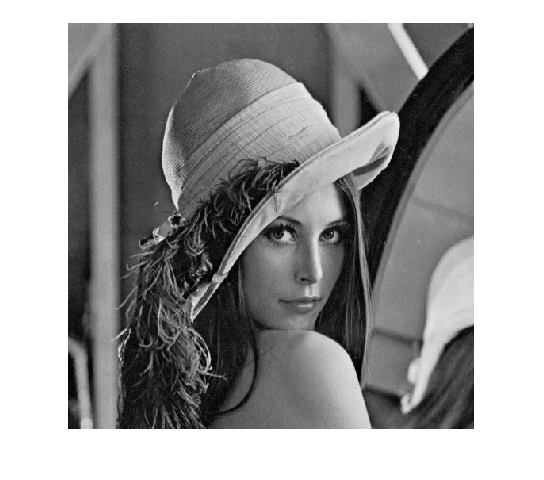

imshow(G, [])

## Exercici: Girar colors imatge

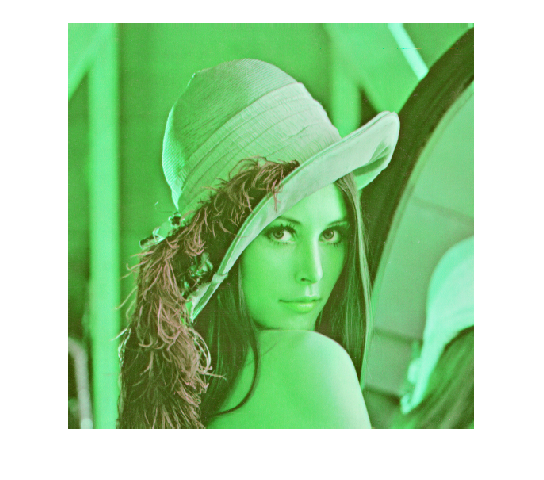

I = imread('lena_color_512.tif');
Ihsv = rgb2hsv(I);
Ihsv(:, :, 1) = mod((Ihsv(:, :, 1) + 1/3), 1.) ;
Irgb = hsv2rgb(Ihsv);
imshow(Irgb)